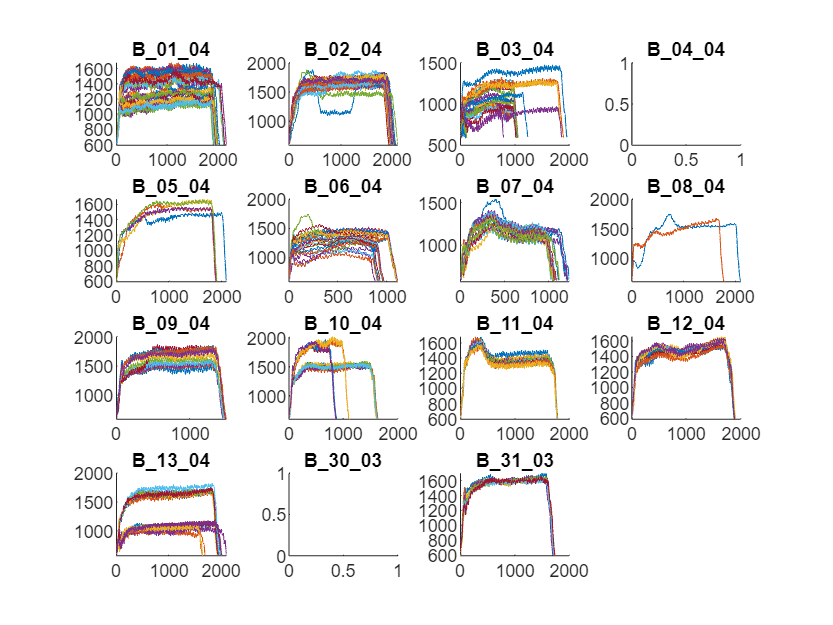

LoadRawData();

pulseThreshold = 600; % Threshold for state detection given by company
minPulseTimeThreshold = 500; % Samples

% Loop through the files, load the data the perform the state detection
% Extract the pulses for each sensor signal based on Signal 20
figure();
signalNumberForDetection = 5;
signalNumberToPlot = 5; % This is signal 21:20
numOfSensors = 12;
[~,numOfFiles] = size(filenames);
mask = {numOfFiles};
flag = {numOfFiles};
pulseData_FunctionOutput = {numOfFiles};
rawDataArray = {numOfFiles};
totalPulses = 1;
for fileIndex=1:numOfFiles
    % Load the data for the current file
    rawDataStruct = load(subfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 

    %pulses is a 2D array with dimensions (1 * numOfPulses)
    [pulseData_FunctionOutput{fileIndex}, mask{fileIndex}, flag{fileIndex}, maxPulseLengths(fileIndex)] = fnStateDetection(rawDataArray{fileIndex}, pulseThreshold, minPulseTimeThreshold, signalNumberForDetection);
    
    % Plot the extracted Signal 20 pulses for this particular file
    subplot(4, 4, fileIndex);
    hold on;
    numOfFalsePulses = 0;
    numOfTruePulses = 0;
    [~, numOfPulses] = size(pulseData_FunctionOutput{fileIndex});
    for pulseIndex=1:numOfPulses
        plot(pulseData_FunctionOutput{fileIndex}{pulseIndex}(:, signalNumberToPlot));
    end
    title(filenames(fileIndex), 'Interpreter', 'none');

    % Combine the pulse data for this file with all the others    
    for pulseIndex = 1:numOfPulses
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSensors % Add data for each sensor
                tempData = pulseData_FunctionOutput{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        end
    end
end

%% Remove DC Offset
%% Pad to the length of longest pulse
maxPulseLength = max(maxPulseLengths) + 1;
for fileIndex = 1:numOfFiles
    for pulseIndex = 1:size(pulseData_FunctionOutput{fileIndex},2)
        temp = pulseData_FunctionOutput{fileIndex}{pulseIndex};
        numSamplesUnderMax = maxPulseLength - size(temp, 1);
        pulseData_DcRemoved{fileIndex}{pulseIndex} = temp - mean(temp, 1);
        pulseData_Padded{fileIndex}{pulseIndex} = padarray (temp, numSamplesUnderMax, 12, "post");
        temp2 = pulseData_Padded{fileIndex}{pulseIndex};
        pulseData_DcRemovedPadded{fileIndex}{pulseIndex} = temp2 - mean(temp2, 1);
    end
end
delete temp;

delete temp2;


%% Combine the data for all padded pulses
totalPulses = 1;
for fileIndex=1:numOfFiles
    for pulseIndex = 1:size(pulseData_FunctionOutput{fileIndex},2)
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSensors % Add data for each sensor
                tempData = pulseData_Padded{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseDataPadded_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseDataDcRemoved_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseDataDcRemovedPadded_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        end
    end
end
delete fileIndex;

delete pulseIndex;

delete tempData;

## Plot padded data

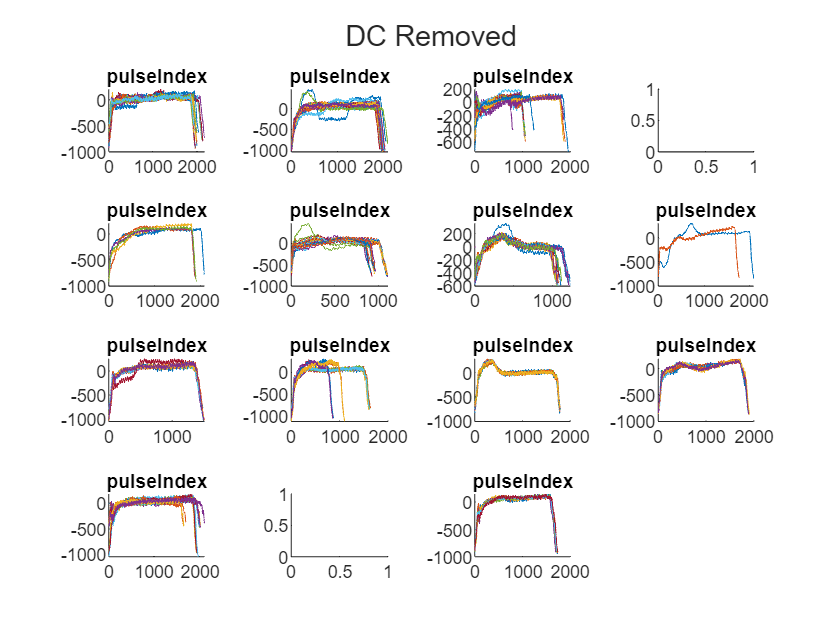

figure();
fg = tiledlayout(4, 4);
%title(fg, 'Padded data');
title(fg, 'DC Removed');
for fileIndex=1:numOfFiles
    %subplot(4, 4, fileIndex); 
    nexttile; hold on;
    for pulseIndex = 1:size(pulseData_Padded{fileIndex},2)
        %plot( pulseData_Padded{fileIndex}{pulseIndex}(:,5) );
        plot( pulseData_DcRemoved{fileIndex}{pulseIndex}(:,5) );
        title('pulseIndex');
    end
end

delete fileIndex;

delete pulseIndex;

## Plot the state detection signal vs 21:20 Actual Moment under Rollers

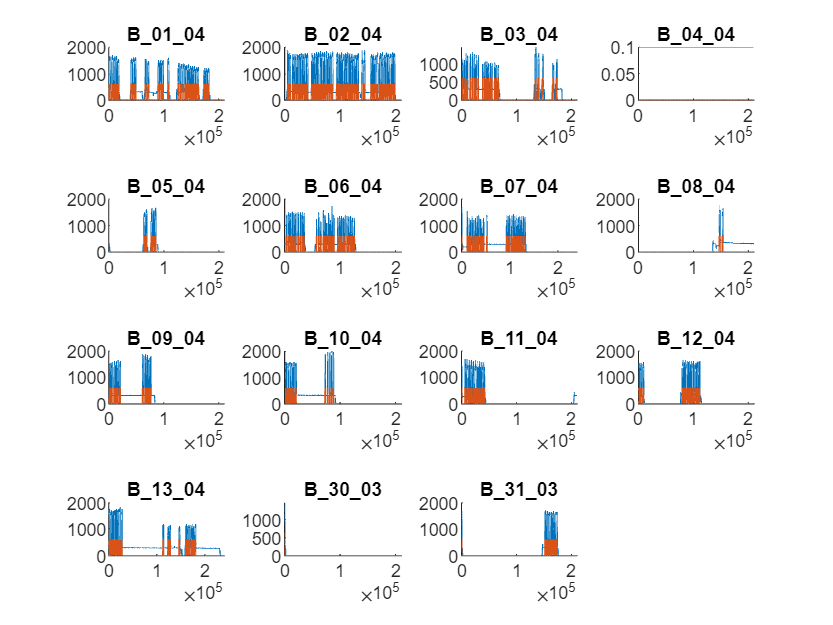

figure();
fg = tiledlayout(4, 4);
%title(fg, 'State detection signal vs 21:20 Actual Moment under Rollers');
for fileIndex=1:numOfFiles
    nexttile; hold on;
    plot(cell2mat(rawDataArray{fileIndex}(signalNumberToPlot, 2)));
    plot(mask{fileIndex});
    title(filenames(fileIndex), 'Interpreter', 'none');
end

delete fileIndex;

%print -depsc 'figures\StateDetectionFig'